# EMSAT

*"A EMSAT possui um total de 7 antenas. Cada uma dessas antenas tem uma certa quantidade de LNBs e que recebem o sinal e os transladam em frequência por meio de rebatimento com o oscilador local de cada LNB e em seguida filtrando-o (****alguns*** ***LNBs filtram a banda lateral inferior, outros a superior****). Dessa forma o sinal chega à Matriz de Comutação SEMPRE em Banda L, com fluxos individualizados de acordo com o LNB que passaram.*

*TrackingMode se refere a forma como o apontamento deve ser feito, se é pra apontar só dando o comando de apontamento pro preset, ou se é pra apontar como LookAngle informando o azimute, elevação e giro do LNB, ou então se é pra usar uma modo mais avançado como o StepTrack (que eu ainda não sei quais os parâmetros necessários pois não testei). TrackingData são os parâmetros a serem passados praquela forma de apontamento específica, exemplo: Preset: T07; LookAngle: 320606 056372 035056 (azimute, elevação e giro, todos com 3 casas inteiras e 3 decimais).*

*A matriz é uma "L-band Switch Matrix" modelo "****NGM-2x****" da ****ETL Systems****. Ela é acessível diretamente ou por telnet na porta 4000 e apenas executa as atividades de comutação entre os diferentes inputs e outputs da estação.*

*Quanto às unidades de controle das antenas (ACU) e os receptores de rastreamento digital (DTR) ambos são acessíveis apenas por uma interface serial RS-485. Como forma de integrá-los a rede, a Kratos especificou a instalação de um conversor Serial-IP que instalamos recentemente chamado de Moxa (acessível no IP ****10.21.205.45****). Cada porta desse IP, a partir da porta 4001 corresponde a um instrumento da estação (existem outros como controladores do ar condicionado, detecção de porta aberta etc).*

*Só é bom saber que tem ****uma antena especifica que não pode ser movimentada remotamente pois a Anatel não comprou a ACU, que é a MCL3.**** Além disso, ****pra banda Ka tem que ser enviado um comando pro próprio LNB mudar o oscilador****.*

*Pra matriz vc pode se conectar diretamente, o Compass não vai interferir pois ele não usa o output do analisador. Só alinha com o pessoal lá da MSAT pq pode ser que a aplicação de coleta esteja usando. ****para a ACU é melhor desabilitar pois o polling do compass é muito frequente, vc vai mandar um comando e receber a mensagem de algo que o compass perguntou****." *(Vinícius Puga)

Aspectos gerais:

- Monitem: 10.21.205.60

- Compass: http://10.21.205.100:5099/RPC2 (admin, newpoint)

- Computador: 10.21.204.39 (anatel_std1 | anatel_master, SATsat321)

- Matriz de banda L: 192.168.0.116:4000 & http://192.168.0.116/

- ACUs: 10.21.205.45:4002 (MCL1), 4003 (MCL2), 4004 (MCL3), 4005 (MKU1), 4006 (MKU2) e 4007 (MCC1).

ipSwitch = '192.168.0.116';
ipACUs   = '10.21.205.45';

# Antenna switch

O controle da matriz de banda L demanda a criação de um socket e o envio da informação textual do campo SET (da variável cSwitch). A matriz, então, responderá com a informação textual do campo GET - caso coincida com a esperada, a configuração foi bem sucedida.

Aspectos críticos:

- O *socket* é desabilitado caso exista uma inatividade de mais de 30 segundos. Consequentemente, deve-se excluir o *socket*, por meio da função clear, criando um novo por meio da função tcpclient.

- A velocidade de comutação que garante a correta configuração da matriz é cerca de 50 ms/comando.

cSwitch = struct('MCL1_V',    struct('set', '{*zs,012,001}0', 'get', '{zBs?012,001}['), ...
                 'MCL1_H',    struct('set', '{*zs,012,002}1', 'get', '{zBs?012,002}\'), ...
                 'MCL2_V',    struct('set', '{*zs,012,003}2', 'get', '{zBs?012,003}]'), ...
                 'MCL2_H',    struct('set', '{*zs,012,004}3', 'get', '{zBs?012,004}^'), ...
                 'MCC1_L',    struct('set', '{*zs,012,005}4', 'get', '{zBs?012,005}_'), ...
                 'MCC1_R',    struct('set', '{*zs,012,006}5', 'get', '{zBs?012,006}`'), ...
                 'MCL3_V',    struct('set', '{*zs,012,007}6', 'get', '{zBs?012,007}a'), ...
                 'MCL3_H',    struct('set', '{*zs,012,008}7', 'get', '{zBs?012,008}b'), ...
                 'MKU1_LO_V', struct('set', '{*zs,012,009}8', 'get', '{zBs?012,009}c'), ...
                 'MKU1_HI_V', struct('set', '{*zs,012,010}0', 'get', '{zBs?012,010}['), ...
                 'MKU1_LO_H', struct('set', '{*zs,012,011}1', 'get', '{zBs?012,011}\'), ...
                 'MKU1_HI_H', struct('set', '{*zs,012,012}2', 'get', '{zBs?012,012}]'), ...
                 'MKU2_LO_V', struct('set', '{*zs,012,013}3', 'get', '{zBs?012,013}^'), ...
                 'MKU2_HI_V', struct('set', '{*zs,012,014}4', 'get', '{zBs?012,014}_'), ...
                 'MKU2_LO_H', struct('set', '{*zs,012,015}5', 'get', '{zBs?012,015}`'), ...
                 'MKU2_HI_H', struct('set', '{*zs,012,016}6', 'get', '{zBs?012,016}a'), ...
                 'MKa1_RHCP', struct('set', '{*zs,012,023}4', 'get', '{zBs?012,023}_'), ...
                 'MKa1_LHCP', struct('set', '{*zs,012,024}5', 'get', '{zBs?012,024}`'));
rxANT = fields(cSwitch)

rxANT = 18×1 cell array
    {'MCL1_V'   }
    {'MCL1_H'   }
    {'MCL2_V'   }
    {'MCL2_H'   }
    {'MCC1_L'   }
    {'MCC1_R'   }
    {'MCL3_V'   }
    {'MCL3_H'   }
    {'MKU1_LO_V'}
    {'MKU1_HI_V'}
    {'MKU1_LO_H'}
    {'MKU1_HI_H'}
    {'MKU2_LO_V'}
    {'MKU2_HI_V'}
    {'MKU2_LO_H'}
    {'MKU2_HI_H'}
    {'MKa1_RHCP'}
    {'MKa1_LHCP'}


## Teste 1 - Tempo de inatividade que desabilita o *socket*: 30 segundos.

O tempo de inatividade que desabilita o socket, "deburrando" o controle da matriz de banda L, foi cerca de 32 segundos nas mais de cinco execuções do teste descrito a seguir. É possível se tratar de parâmetro configurável na própria matriz.

hSwitch = tcpclient(ipSwitch, 4000);

PAUSE = 25;
while true
    try
        writeline(hSwitch, getfield(cSwitch, rxANT{1}).set); pause(.1); msg = read(hSwitch, hSwitch.NumBytesAvailable, 'char');
        fprintf('Inatividade: %.0f segudos, resposta: %s', PAUSE, msg)
        if ~isempty(msg)
            pause(PAUSE) % Inatividade...
        end

    catch ME
        ME.message
        break
    end
    PAUSE = PAUSE+1;
end

Inatividade: 25 segudos, resposta: {zBs?012,001}[Inatividade: 26 segudos, resposta: {zBs?012,001}[Inatividade: 27 segudos, resposta: {zBs?012,001}[Inatividade: 28 segudos, resposta: {zBs?012,001}[Inatividade: 29 segudos, resposta: {zBs?012,001}[Inatividade: 30 segudos, resposta: {zBs?012,001}[Inatividade: 31 segudos, resposta: {zBs?012,001}[Inatividade: 32 segudos, resposta: 

ans = 'Invalid operation. Object must be connected to the remote server.'

PAUSE

PAUSE = 33

clear hSwitch

## Teste 2 - Velocidade de Comutação: 50 ms/comando.

O código abaixo foi executado diversas vezes, evidenciando erros quando o pause entre chamadas consecutivas é 35 ms. A partir de 40 ms, entretanto, não foi evidenciado erro. É prudente, portanto, usar ao menos 50 ms.

A função **writeread** não deve ser usada porque a informação retornada pelo comutador não possui um dos terminadores esperados pelo objeto tcpclient ("CR", "LF" ou "CR/LF"). 

A efetividade da comutação pode ser observada pelas respostas da matriz (no corpo do código) ou no ambiente web (http://192.168.0.116/), com a ressalva que o ambiente web só consegue atualizar corretamente quando o pause é maior ou igual a 1 segundo.

hSwitch = tcpclient(ipSwitch, 4000);

% PAUSE = 1; % Possibilita visualização do chaveamento no ambiente web.
PAUSE = .05;
for ii = 1:numel(rxANT)
    writeline(hSwitch, getfield(cSwitch, rxANT{ii}).set);
    pause(PAUSE);
    response = read(hSwitch, hSwitch.NumBytesAvailable, 'char')
    
    if ~strcmp(getfield(cSwitch, rxANT{ii}).get, response)
        fprintf('Ops... erro na configuração da %s\n', rxANT{ii})
    end
end

response = '{zBs?012,001}['

response = '{zBs?012,002}\'

response = '{zBs?012,003}]'

response = '{zBs?012,004}^'

response = '{zBs?012,005}_'

response = '{zBs?012,006}`'

response = '{zBs?012,007}a'

response = '{zBs?012,008}b'

response = '{zBs?012,009}c'

response = '{zBs?012,010}['

response = '{zBs?012,011}\'

response = '{zBs?012,012}]'

response = '{zBs?012,013}^'

response = '{zBs?012,014}_'

response = '{zBs?012,015}`'

response = '{zBs?012,016}a'

response = '{zBs?012,023}_'

response = '{zBs?012,024}`'

clear hSwitch

# ACUs

O controle das ACUSs demanda a criação de um socket e o envio da informação textual. Diferente do controle da matriz, a mensagem textual enviada pelas ACUs possui o terminador "CR/LF" (carriege return e line feed).

Aspectos críticos:

- É necessário desabilitar, no Compass, a gestão da ACU. O Compass envia, num loop infinito, muitas requisições, de forma que um socket concorrendo com o Compass faria as respostas se "perderam" no universo de informação. Por conta disso, importante dar um **flush** antes do envio da comunicação e usar **regexp** pra tratar as suas respostas (além de desabilitar no Compass o controle da ACU).

- A ACU demora cerca de 1 segundo para responder algumas das requisições mais complexas - como a lista de alvos de uma ACU.

hMCL1    = tcpclient(ipACUs, 4002);
configureTerminator(hMCL1, "CR/LF") % uint8([13 10])

% hMCL2   = tcpclient(ipACUs, 4003);
% hMCL3   = tcpclient(ipACUs, 4004);
% hMKU1   = tcpclient(ipACUs, 4005);
% hMKU2   = tcpclient(ipACUs, 4006);
% hMCC1   = tcpclient(ipACUs, 4007);

flush(hMCL1)

Exemplo de resposta aos comandos do Compass:

msg2write = read(hMCL1, hMCL1.NumBytesAvailable, "char")

msg2write =     'AX320320Y056576Z323983S-279T07M0303H0P0U53CX320323Y056585Z324000FFRF00951000A000I1C0
     > 1
     > ""
     > ""
     > 02 00 0000 290000 063700 000357
     > 951.000
     > 00000000 00000000 00000000 00000000
     > 290.00 63.50 0.4
     > 0.00 0.20 0.0
     > 1 1 0
     > 0.01 0.01 0.1
     > 1
     > 1
     > 04/06/2023
     > "MCL-1"
     > 2
     >03
     > 1
     > 0
     > 1
     >
     !00105 ERROR: EDIT: Unknown or unavailable command
     >O0stm
     >opdmvfusl
     >spclfdwme
     >B0nsweao
     > Port 5 at supervisor
     > "IS-1R"
     > 03 00 0000 342847 062213 344200
     >AX320320Y056576Z323983S-293T07M0303H0P0U53CX320323Y056585Z324000FFRF00951000A000I1C0
     > 0
     > "IS-11"
     > "IS-1R"
     > 03 00 0000 342847 062213 344200
     > 1
     > 00000000 00000000 00000000 00000000
     > 342.85 62.21
     > -50.000
     > 0.00 0.00 0.0
     > -15.8
     > 320.32 56.58 -36.0
     > 1000 1000 1000
     > 270.00 10.50 -70.0
     > -43.178611
     > 0
  

## Teste 1 - Comandos mais importantes.

flush(hMCL1)
PAUSE = 1;

% Antena atual.
writeline(hMCL1, '/ CONFIGS SITE ANTENNA'); pause(PAUSE); read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' "MCL-1"
     >'


% Mensagem esperada é "Port 5 at supervisor", indicando que ACU pode ser controlada.
writeline(hMCL1, 'WHO'); pause(PAUSE); read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' Port 5 at supervisor
     >'


% Mensagem esperada é "00000000 00000000 00000000 00000000", indicando que não há registro de erro na ACU.
writeline(hMCL1, 'F 0'); pause(PAUSE); read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' 00000000 00000000 00000000 00000000
     >'


% Azimute, elevação e giro do LNB da antena atual.
writeline(hMCL1, '/ CONFIGS ENCODERS CURRENT'); pause(PAUSE), read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' 320.31 56.59 -36.0
     >'


% Lista de alvos da antena atual (cadastro do Compass).
writeline(hMCL1, '/ TRACKING TRACK LS'); pause(PAUSE); read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     '
     Menu "Track a target"
       0 X T01 ""
       1 X T02 "IS-11"
       2 X T03 "IS-14"
       3 X T04 "IS-1R"
       4 X T05 "IS-805"
       5 X T06 "IS-21"
       6 X T07 "HM-AMAZONAS3"
       7 X T08 "SC-C2"
       8 X T09 "SO-B2"
       9 X T10 "SO-D2"
      10 X T11 "!SO-C3"
      11 X T12 "!SO-B4"
      12 X T13 "!IS-GALAX 28"
      13 X T14 "!SO-B3"
      14 X T15 "!TS-ANIK G1"
      15 X T16 "IS-9"
      16 X T17 "IS-34"
      17 X T18 "!TS-ANIK F1"
      18 X T19 "IS-29"
      19 X T20 "SO-D1"
      20 X T21 "SS-SES 4"
      21 X T22 "IS-907"
      22 X T23 "ES-65W"
      23 X T24 "!IS-10-02"
      24 X T25 "IS-23"
      25 X T26 "SS-NSS 806"
      26 X T27 "IS 35e"
      27 X T28 "SS-SES 6"
      28 X T29 "!ES-8 WEST B"
      29 X T30 "HM-AMAZONAS2"
      30 X T31 "SS-AMC 12"
      31 X T32 "!IS-901"
      32 X T33 "E65WA"
      47 X T48 "Test Sat"
      49 X T50 "teste"
     >'


Trata-se de uma expressão regular com a indicação de todos os alvos ativos. Armazenar informação como 'T03 "IS-14"' e, quando da construção do comando, enviar apenas 'T03'. O nome do campo seria "Alvo (ID/Nome)".

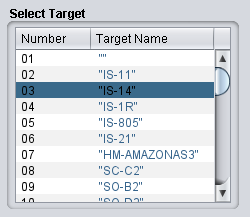

% Especificação de um dos alvos.
writeline(hMCL1, 'TT 07'); pause(PAUSE); read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' 03 00 0000 320323 056585 324000
     >'


## Teste 2 - Tempo de resposta.

O tempo de resposta médio da ACU é inferior a 1ms. Não é possível, entretanto, usar a função **writeread**, mas as funções **writeline** e **read**, concatenadas com um *pause* entre elas.

flush(hMCL1)

ansTime = zeros(100,1);
for ii = 1:100
    writeline(hMCL1, 'TT 51')
    tic
    while ~hMCL1.NumBytesAvailable
        break
    end
    ansTime(ii) = toc;
    flush(hMCL1)
end

sprintf('Mediana: %.3f ms\nMáxima: %.3f ms', median(ansTime)*1000, max(ansTime)*1000)

ans =     'Mediana: 0.184 ms
     Máxima: 1.364 ms'


## Teste 3 - Compara informações obtidas da ACU com as apresentadas no Compass.

Tentativa de obter informações de um *target* da ACU (a lista vai de 1 a 50). Resposta quando inserido um valor fora da faixa: "!00402 ERROR: 51: Value out of range"

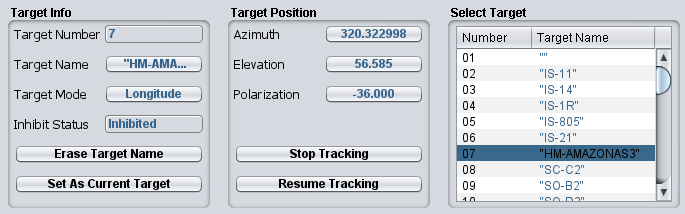

flush(hMCL1)
writeline(hMCL1, 'TT 07')
pause(.1)
read(hMCL1, hMCL1.NumBytesAvailable, 'char')

ans =     ' 03 00 0000 320323 056585 324000
     >'


Expressão regular:

- Azimuth: 320.323º

- Elevation: 56.585º

- Polarization: 324.000º (ou -36.000º)

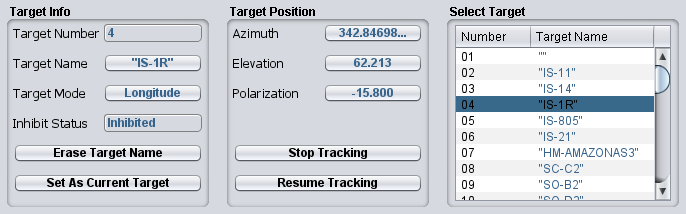

flush(hMCL1)
writeline(hMCL1, 'TT 04')
pause(.1)
txtAns = read(hMCL1, hMCL1.NumBytesAvailable, 'char')

txtAns =     ' 03 00 0000 342847 062213 344200
     >'


## Teste 4 - Movimentação da antena e giro LNB.

% POSIÇÃO ATUAL
writeline(hMCL1, '/ CONFIGS ENCODERS CURRENT'); pause(1), rawOldPosition = read(hMCL1, hMCL1.NumBytesAvailable, 'char')

rawOldPosition =     ' 342.85 62.22 -15.9
     >'


OldPosition = regexp(rawOldPosition, '(?<Azimuth>\d{1,3}.\d{1,3}) (?<Elevation>\d{1,3}.\d{1,3}) (?<Polarization>[-]\d{1,3}.\d{1,3})', 'names');
if ~isempty(OldPosition)
    OldPosition = OldPosition(end);
    
    OldPosition.Azimuth      = str2double(OldPosition.Azimuth);
    OldPosition.Elevation    = str2double(OldPosition.Elevation);
    OldPosition.Polarization = str2double(OldPosition.Polarization);
    if OldPosition.Polarization < 0; OldPosition.Polarization = 360+OldPosition.Polarization;
    end
end
OldPosition

OldPosition = struct with fields:
         Azimuth: 342.8500
       Elevation: 62.2200
    Polarization: 344.1000



% LOOP ENTRE TT 04 E TT 07
if     isequal(OldPosition, struct('Azimuth', 342.85, 'Elevation', 62.22, 'Polarization', 344.1)); Target = 'TT 07';
elseif isequal(OldPosition, struct('Azimuth', 320.31, 'Elevation', 56.59, 'Polarization', 324));   Target = 'TT 04';
else   error('Defina manualmente o destino porque atualmente não estão configurados nem o TT 04 e nem o TT 07.');
end

% POSIÇÃO PRETENDIDA
writeline(hMCL1, Target); pause(1); rawNewPosition = read(hMCL1, hMCL1.NumBytesAvailable, 'char')

rawNewPosition =     ' 03 00 0000 320323 056585 324000
     >'


NewPosition = regexp(rawNewPosition, '\d{2} \d{2} \d{4} (?<Azimuth>\d{6}) (?<Elevation>\d{6}) (?<Polarization>\d{6})', 'names');
if ~isempty(NewPosition)
    NewPosition = NewPosition(end);
    
    NewPosition.Azimuth      = str2double(NewPosition.Azimuth)      / 1e+3;
    NewPosition.Elevation    = str2double(NewPosition.Elevation)    / 1e+3;
    NewPosition.Polarization = str2double(NewPosition.Polarization) / 1e+3;
end
NewPosition

NewPosition = struct with fields:
         Azimuth: 320.3230
       Elevation: 56.5850
    Polarization: 324


movMatrix = zeros(3,3);
movMatrix(1,:) = [OldPosition.Azimuth, OldPosition.Elevation, OldPosition.Polarization];

writeline(hMCL1, Target+" T");
tic

while true
    pause(10)

    writeline(hMCL1, '/ CONFIGS ENCODERS CURRENT'); pause(1), rawMovPosition = read(hMCL1, hMCL1.NumBytesAvailable, 'char');
    MovPosition = regexp(rawMovPosition, '(?<Azimuth>\d{1,3}.\d{1,3}) (?<Elevation>\d{1,3}.\d{1,3}) (?<Polarization>[-]\d{1,3}.\d{1,3})', 'names');
    if ~isempty(MovPosition)
        MovPosition = MovPosition(end);
        
        MovPosition.Azimuth      = str2double(MovPosition.Azimuth);
        MovPosition.Elevation    = str2double(MovPosition.Elevation);
        MovPosition.Polarization = str2double(MovPosition.Polarization);
        if MovPosition.Polarization < 0; MovPosition.Polarization = 360+MovPosition.Polarization;
        end

        movMatrix(2,:) = movMatrix(3,:); % na linha 1 a posição inicial, na linha 2 a posição atual, na linha 3 a posição identificada na iteração anterior
        movMatrix(3,:) = [MovPosition.Azimuth, MovPosition.Elevation, MovPosition.Polarization];

        varMatrix = [abs(diff(movMatrix([1,3],:))); abs(diff(movMatrix([2,3],:)))];
        if isequal(varMatrix(1,:), [0,0,0])
            fprintf('Antena não está se movimentando, estando parada na sua posição inicial....\n')
        elseif isequal(varMatrix(2,:), [0,0,0])
            fprintf('Antena parou de se movimentar.\n')
            break
        else
            fprintf('Em %.3f segundos, a antena variou o seu azimute em %.3f graus, a sua elevação em %.3f graus e a sua polarização em %.3f graus.\n', ...
                    toc, varMatrix(1,1), varMatrix(1,2), varMatrix(1,3))
        end
    end
end

Em 22.487 segundos, a antena variou o seu azimute em 2.320 graus, a sua elevação em 2.450 graus e a sua polarização em 9.900 graus.
Em 33.575 segundos, a antena variou o seu azimute em 7.970 graus, a sua elevação em 4.990 graus e a sua polarização em 20.100 graus.
Em 44.594 segundos, a antena variou o seu azimute em 10.690 graus, a sua elevação em 5.550 graus e a sua polarização em 20.100 graus.
Em 55.612 segundos, a antena variou o seu azimute em 13.350 graus, a sua elevação em 5.640 graus e a sua polarização em 20.100 graus.
Em 66.634 segundos, a antena variou o seu azimute em 16.010 graus, a sua elevação em 5.640 graus e a sua polarização em 20.100 graus.
Em 77.655 segundos, a antena variou o seu azimute em 18.660 graus, a sua elevação em 5.640 graus e a sua polarização em 20.100 graus.
Em 88.688 segundos, a antena variou o seu azimute em 21.170 graus, a sua elevação em 5.640 graus e a sua polarização em 20.100 graus.
Em 99.717 segundos, a antena variou o seu azimute em 21.720 graus

Antena atingiu o alvo.


% TT 07 T ->Move para o preset 07
% Q -> Coloca em Idle
% S -> Suspende a movimentação
% R -> Resume